Purpose of this document:

Test the correct solution of an MPC sub-problem of trajectory following using repurposed class definition vehOCP.

The MPC sub-problem is characterized by:

- A shorter time window than the full problem (obj.T)

- A smaller discretization number than the full problem (obj.N)

% MPC subproblem settings
T = 0.5;    % seconds
N = 20;     % number of control intervals

clear sol;
OCP = vehOCP(N,T);
OCP.build_basics();
OCP.add_reference();    % default: vxRef = 10, vyRef = 0, pyRef = 0;
OCP.add_objective();
% manually change the collision criteria
% OCP.build_debug_var(); % for debug, run this function
OCP.add_control_bounds(); % use default bounds
v_xb0 = 10; v_yb0 = 0; px0 = 1; py0 = 0; r0 = 0; psi0 = 0; omega_f0 = 30; omega_r0 = 30; delta0 = 0;
OCP.add_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
% OCP.add_approx_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
% OCP.add_initial_conditions(5,0,0,5,5,0,30,30,0); % initially spinning
OCP.add_path_constraints(px0,py0,10,2); % within +-5 of px0, and +-2 in py0
OCP.add_ego_centers();
OCP.set_solver_init(10, 0, 0, 0, 0, 0, 30, 30, 0);  % vx,vy,px,py,r,psi,wf,wr,delta
% solver options
% solver_opts = struct('max_iter',500,'print_level',0);
solver_opts = struct('max_iter',500);
plugin_opts = struct('print_time',true);
% solver_opts = struct('max_iter',1000,'hessian_approximation','limited-memory','tol',1e-3);
try
    sol = OCP.solve(plugin_opts,solver_opts);
catch
    disp("Solution Not Found.");
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1569
Number of nonzeros in inequality constraint Jacobian.:      102
Number of nonzeros in Lagrangian Hessian.............:      723

Total number of variables............................:      229
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      189
Total number of inequality constraints...............:      102
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      102
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

Solution Not Found.


if ~exist('sol','var')
    foundSol = false
    sol = OCP.opti.debug;
else
    foundSol = true
end

foundSol = logical
   0


If the solver has a solution, we can visualize the states, intermediate variables, controls.

If the solver failed, we can still use opti.debug.value() to investigate the values of variables.

% if solutin is found, set foundSol = true. Otherwise set foundSol = false, and 
% the debug results will be used instead.
[cost, cost_vx, cost_vy, cost_py] = pp.calculate_cost(OCP,sol,foundSol)

cost = 40.7505

cost_vx = 18.7658

cost_vy = 0.4180

cost_py = 21.5667

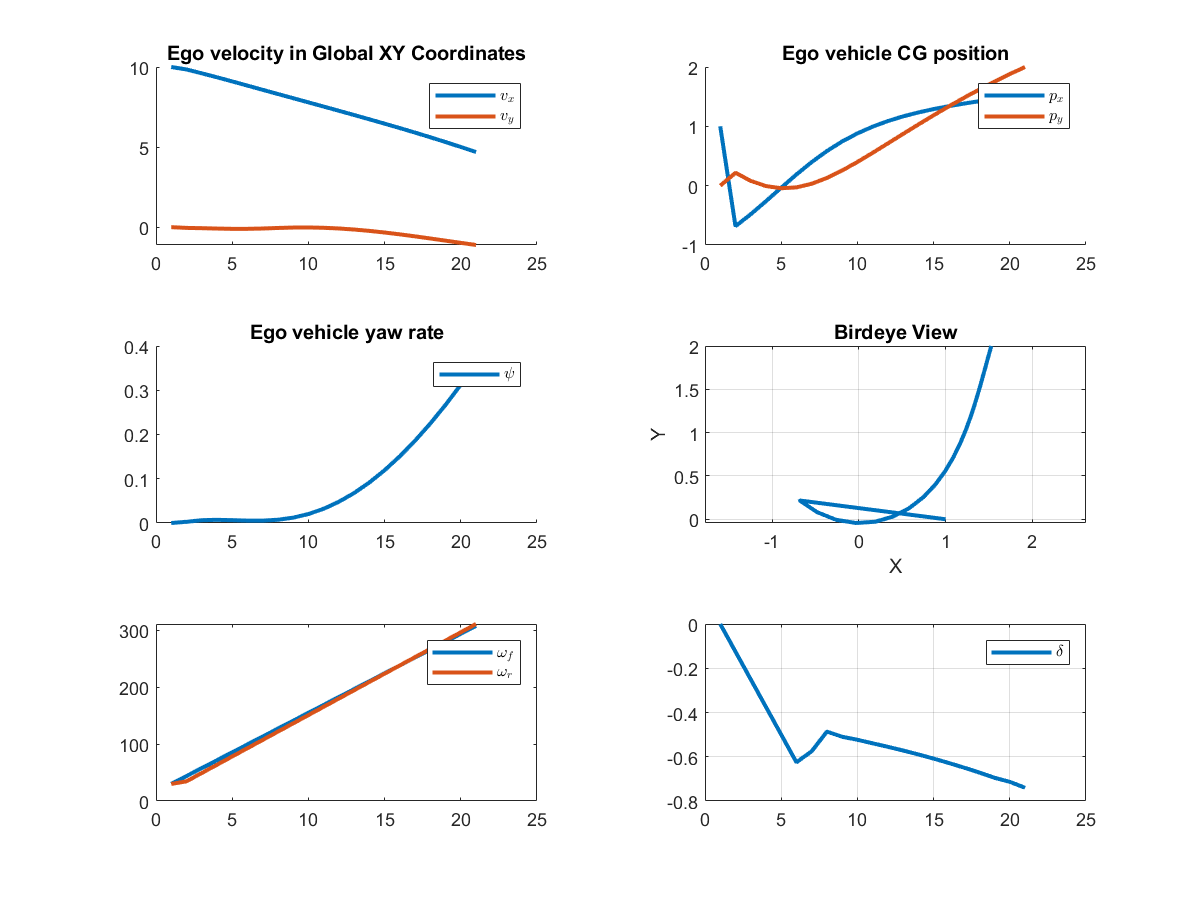

pp.basic_plots_dugoff(OCP,sol);

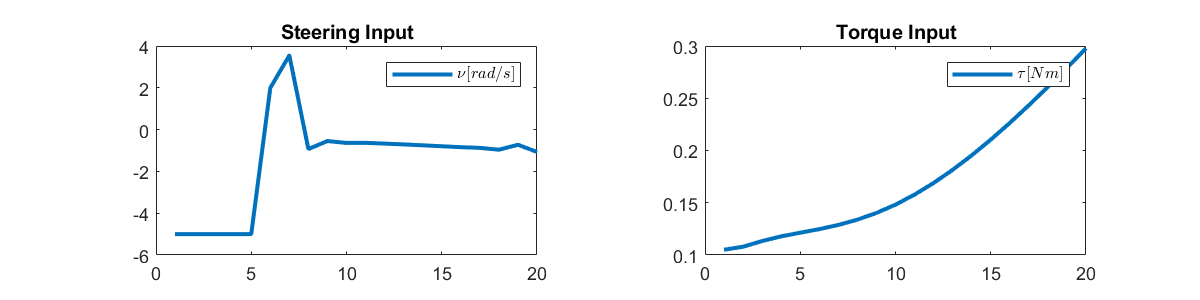

pp.controls_plot_dugoff(OCP,sol)

% pp.debug_plot(OCP,sol,foundSol)

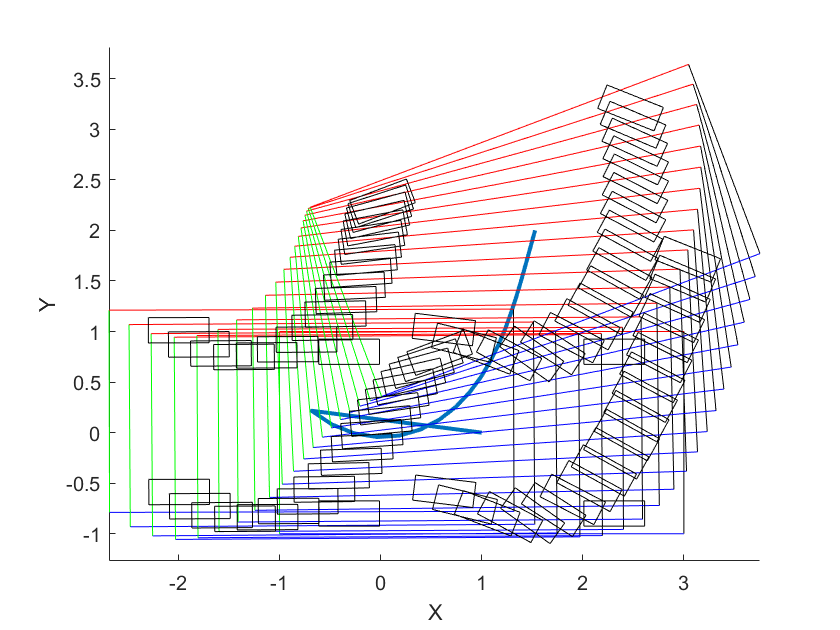

pp.rectangle_overlap(OCP,sol);

Use the 3-circle representation:

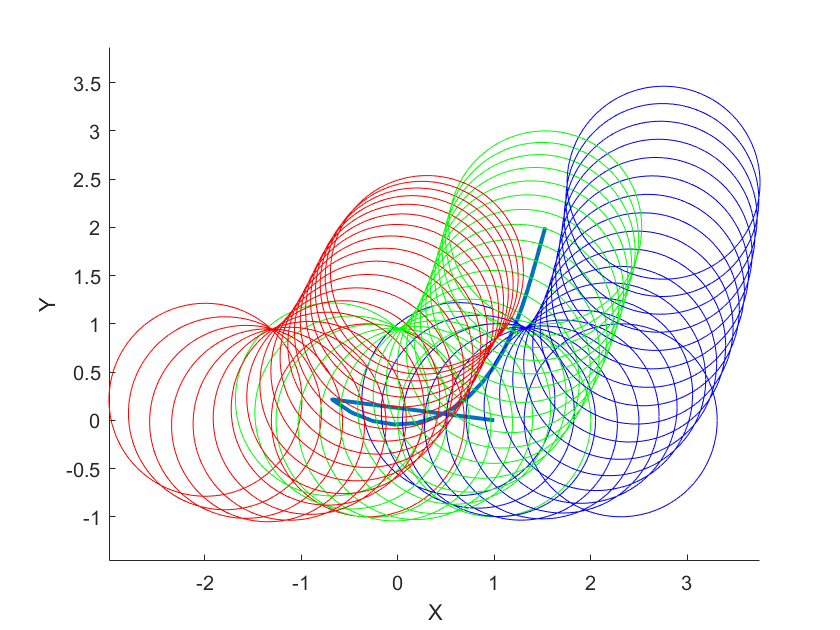

pp.circles_overlap(OCP,sol);

Check constraint violations (cv)

cv_control_bounds = dbg.control_bounds_violation(sol, OCP, 5, 1000)

cv_control_bounds = 7.6108e-08

cv_initial_constraints = dbg.initial_constraints_violation(sol, OCP, v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0)

cv_initial_constraints = 1.1388e-10

cv_path_constraints = dbg.path_constraints_violation(sol,OCP,px0,py0,5,2)

cv_path_constraints = 1.9989e-08

% cv_collision_violation = dbg.collision_constraints_violation(sol,OCP)
cv_dynamic_constraints = dbg.dynamic_constraints_violation(sol, OCP)

cv_dynamic_constraints = 1.8043

Animation

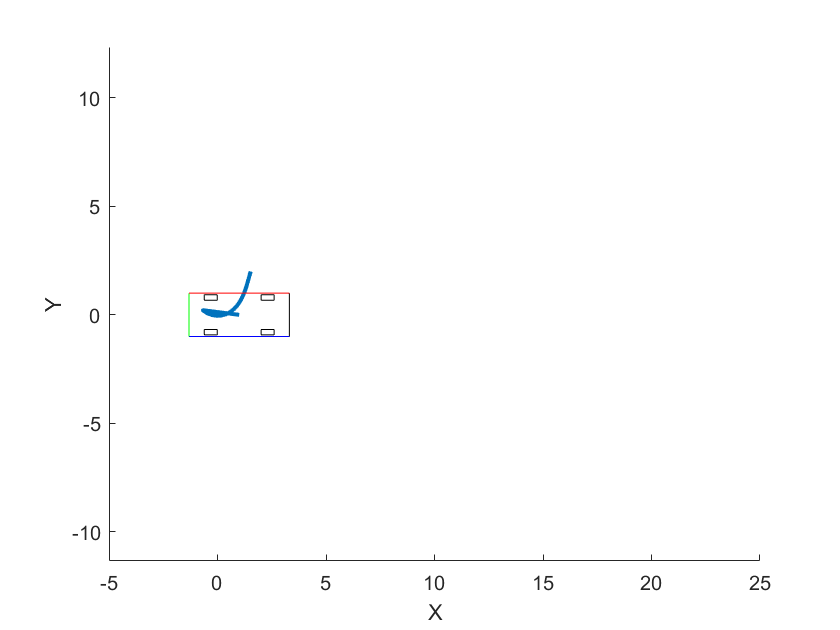

Video saved as: C:\github\vehicle-MPC-CasADi-MATLAB\src\video.avi


pp.make_video_rectangles(OCP,sol,'video',foundSol);